## Load and process raw connectivity .csv file

parentDir = 'C:\Users\Wilson Lab\Google Drive\Lab Work\LH-DAN_connectomics_analysis';

tbl = readtable(fullfile(parentDir, 'cosine_similarity_analysis_data_all_DANs.csv'), ...
    'delimiter', ',');

Drop all the neurons that are fragments with somata in the left hemisphere    

tbl = tbl(~contains(tbl.neuronName, '_L'), :); 

Convert the values in the neuronIDs column from numeric to string, then re-save the data as a .mat file

neuronIDs = {};
for i=1:size(tbl, 1)
    if ~mod(i, 100000)
        disp([num2str(i), ' of ', num2str(size(tbl, 1))])
    end
    neuronIDs{i} = num2str(tbl.neuronID(i));
end

100000 of 316942
200000 of 316942
300000 of 316942


tbl.neuronID = neuronIDs';
% save(fullfile(parentDir, 'cosine_similarity_analysis_data_all_DANs.mat'), 'tbl');


## Load pre-processed data

% parentDir = 'C:\Users\Wilson Lab\Google Drive\Lab Work\LH-DAN_connectomics_analysis';
% 
% load(fullfile(parentDir, 'cosine_similarity_analysis_data_all_DANs.mat'), 'tbl');

## Filter by direction and partner type

dt = DataTable(tbl);
filterDefs = struct();
filterDefs.partnerDirection = 'downstream';
filterDefs.status = 'Traced';
filterDefs.partnerCropped = 'FALSE';
dt = dt.initialize_filters(filterDefs);
sb = dt.subset;


### Sum together synapse counts for neurons of the same cell type

Except for PPM1201 and (maybe) PAM12, which are analyzed as individual neurons.

% Get list of neuron counts for each cell type
neuronList = sortrows(unique(sb(:, {'neuronID', 'neuronName'})), 2);

% Add suffixes to make neurons into a unique cell type before grouping
individualAnalysisTypes = {'PPM1201_R'};
for iType = 1:numel(individualAnalysisTypes)
    sb = convert_to_unique_names(sb, neuronList, individualAnalysisTypes{iType});
end

% Update neuronList
neuronList = sortrows(unique(sb(:, {'neuronID', 'neuronName'})), 2);

% Now sum together synapse counts for neurons of the same cell type
groupCounts = groupsummary(neuronList, 'neuronName');
grpTbl = [];
for iType = 1:size(groupCounts, 1)
%     disp([num2str(iType), ' of ', num2str(size(groupCounts, 1))]);
    currData = sb(strcmp(sb.neuronName, groupCounts.neuronName{iType}), :);
    newRows = groupsummary(currData, {'neuronName', 'neuronType', 'partnerID', 'partnerName', ...
        'partnerType', 'partnerDirection'}, 'sum', 'synapseCount');
    newRows.Properties.VariableNames{strcmp(newRows.Properties.VariableNames, 'sum_synapseCount')} = ...
        'synapseCount';
    grpTbl = [grpTbl; newRows];
end
% Update neuronList
neuronList = unique(grpTbl.neuronName);

## Calculate pairwise cosine similarity

csMat = [];
for iType = 1:size(neuronList, 1)
    disp([num2str(iType), ' of ', num2str(size(neuronList, 1))]);
    currNeuron = neuronList{iType};
    for iCompType = 1:size(neuronList, 1)
        currCompNeuron = neuronList{iCompType};
        if iCompType >= iType
            csMat(iType, iCompType) = compute_similarity(grpTbl, currNeuron, currCompNeuron);
        else
            csMat(iType, iCompType) = csMat(iCompType, iType);
        end
    end
end

1 of 45
2 of 45
3 of 45
4 of 45
5 of 45
6 of 45
7 of 45
8 of 45
9 of 45
10 of 45
11 of 45
12 of 45
13 of 45
14 of 45
15 of 45
16 of 45
17 of 45
18 of 45
19 of 45
20 of 45
21 of 45
22 of 45
23 of 45
24 of 45
25 of 45
26 of 45
27 of 45
28 of 45
29 of 45
30 of 45
31 of 45
32 of 45
33 of 45
34 of 45
35 of 45
36 of 45
37 of 45
38 of 45
39 of 45
40 of 45
41 of 45
42 of 45
43 of 45
44 of 45
45 of 45


#### Save similarity matrix

saveFileName = ['csMat_all_DANs_', filterDefs.partnerDirection, '.mat'];
if ~exist(fullfile(parentDir, saveFileName), 'file')
    save(fullfile(parentDir, saveFileName), 'csMat', 'neuronList');
else
    error('That file already exists')
end

## Load saved similarity matrices

parentDir = 'C:\Users\Wilson Lab\Google Drive\Lab Work\LH-DAN_connectomics_analysis';

fileName = 'csMat_all_DANs_PAM12_ungrouped';

% Upstream
load(fullfile(parentDir, [fileName, '_upstream.mat']), 'csMat', 'neuronList')
[cs_us, neuronList_us] = reorder(csMat, neuronList);

% Downstream
load(fullfile(parentDir, [fileName, '_downstream.mat']), 'csMat', 'neuronList')
[cs_ds, neuronList_ds] = reorder(csMat, neuronList);

% % Drop all MB-DANs
% sz = size(neuronList_ds, 1);
% cs_ds = cs_ds(sz-15:sz, sz-15:sz);
% cs_us = cs_us(sz-15:sz, sz-15:sz);
% neuronList_ds = neuronList_ds(sz-15:sz, :);
% neuronList_us = neuronList_us(sz-15:sz, :);

% Drop all non-MB-DANs except PPL201, PPL203, and PPM1201
targetInds = contains(neuronList_ds.neuronName, 'PAM') | contains(neuronList_ds.neuronName, 'PPL1') | ...
    contains(neuronList_ds.neuronName, 'PPL201') | contains(neuronList_ds.neuronName, 'PPL203') | ...
    contains(neuronList_ds.neuronName, 'PPM1201');
cs_ds = cs_ds(targetInds, targetInds);
cs_us = cs_us(targetInds, targetInds);
neuronList_us = neuronList_us(targetInds, :);
neuronList_ds = neuronList_ds(targetInds, :);

## PLOT COSINE SIMILARITY MATRIX

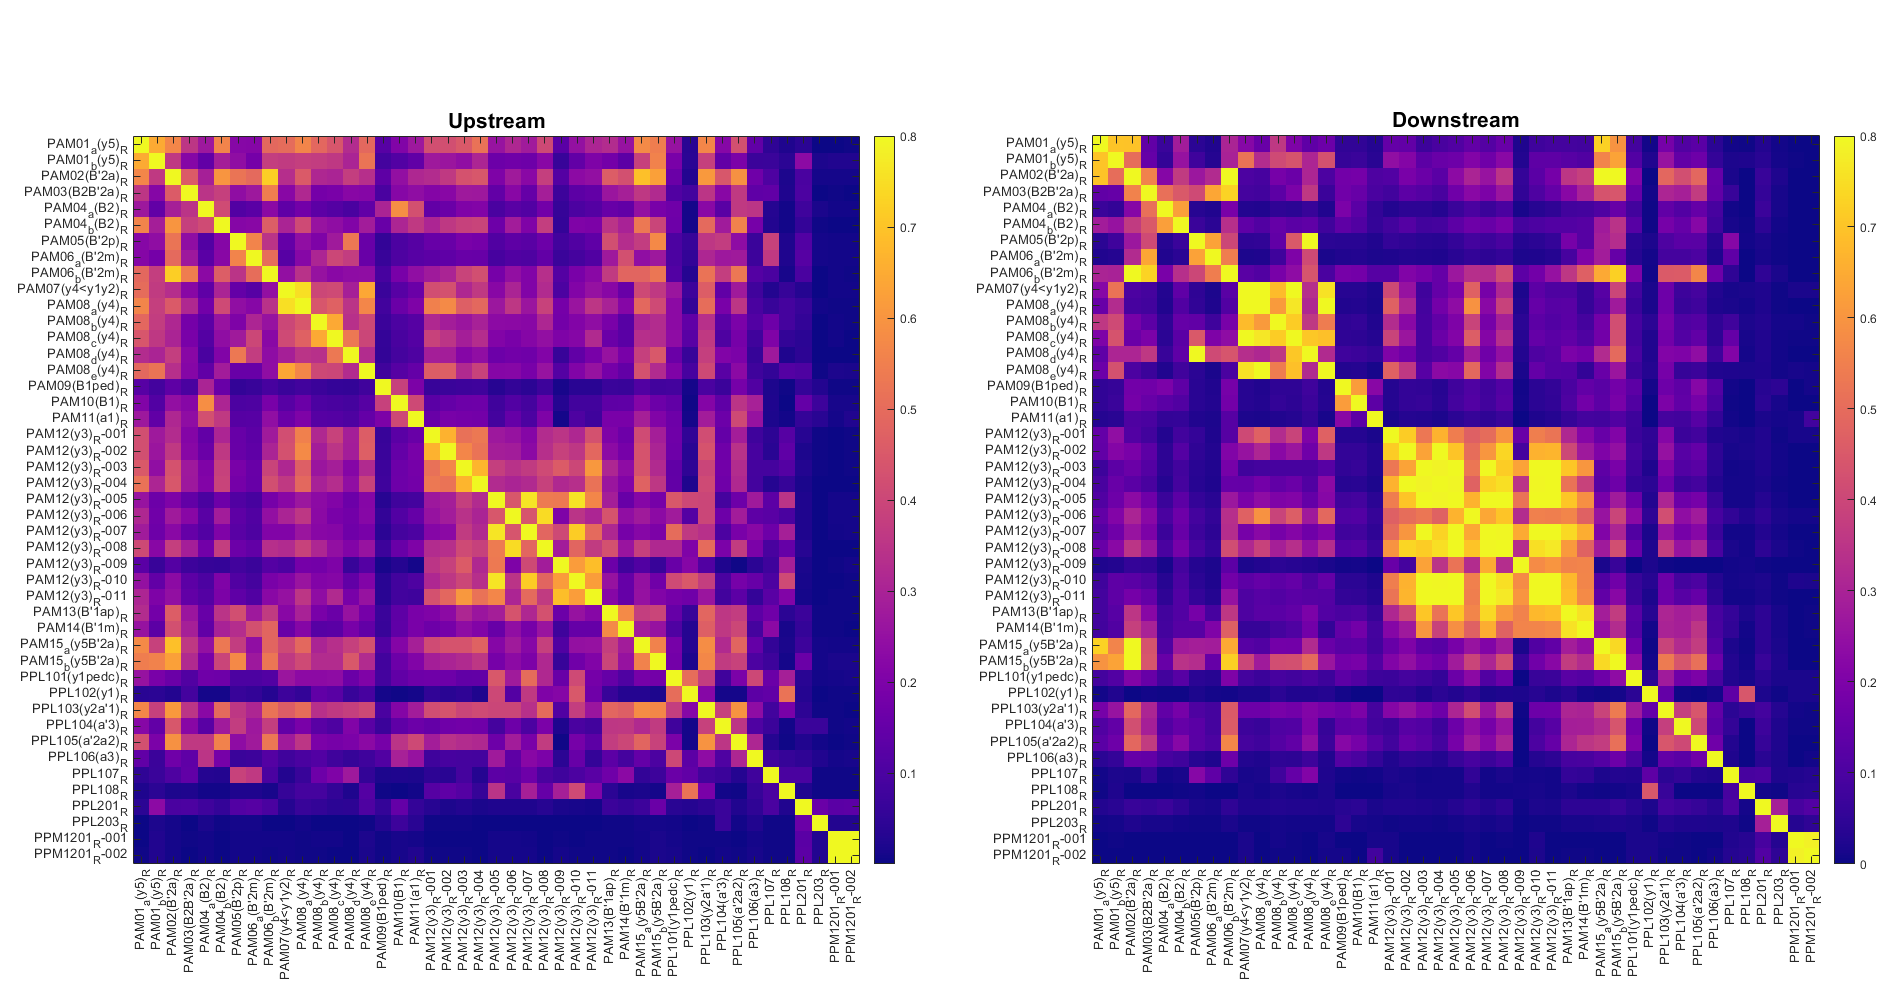

capVal = 0.8;

f = figure(2); clf;
f.Position(3:4) = [1900 1000];
ax = subaxis(1, 2, 1, 'sh', 0.09, 'ml', 0.07, 'mr', 0.01);
plotData = cs_us;
plotData(plotData > capVal) = capVal;
imagesc(plotData);
ax.XTick = 1:size(neuronList, 1);
ax.YTick = 1:size(neuronList, 1);
ax.XTickLabel = neuronList_us.neuronName;
ax.XTickLabelRotation = 90;
ax.YTickLabel = neuronList_us.neuronName;
title('Upstream', 'FontSize', 16)
axis square
colorbar();

ax = subaxis(1, 2, 2);
plotData = cs_ds;
plotData(plotData > capVal) = capVal;
imagesc(plotData);
ax.XTick = 1:size(neuronList, 1);
ax.YTick = 1:size(neuronList, 1);
ax.XTickLabel = neuronList_ds.neuronName;
ax.XTickLabelRotation = 90;
ax.YTickLabel = neuronList_ds.neuronName;
title('Downstream', 'FontSize', 16)
axis square
colorbar();
colormap(plasma)

save_figure(gcf(), parentDir, 'DAN_similarity_PAM12_ungrouped_08_capVal')

## Local functions

#### [cs, neuronList] = reorder(csMat, neuronList)

function [csMat, nlTb] = reorder(csMat, neuronList)

Put all the PAM and PPL1 cluster DANs at the beginning of the list

sortNums = zeros(size(neuronList, 1), 1);
originalNums = 1:size(neuronList, 1);
PAMlocs = contains(neuronList, 'PAM');
PPL1locs = contains(neuronList, 'PPL1');
sortNums(PPL1locs) = 1;
sortNums(PAMlocs) = 2;
nlTb = table(neuronList, 'VariableNames', {'neuronName'});
nlTb.sortNums = sortNums;
nlTb.originalNums = originalNums';
nlTb = sortrows(nlTb, 'sortNums', 'descend');
csMat = csMat(nlTb.originalNums, nlTb.originalNums);
end

#### Cs = compute_similarity(tbl, neuron_1, neuron_2)

function Cs = compute_similarity(tbl, neuron_1, neuron_2)

% Separate data for target neurons
sb_1 = tbl(strcmp(tbl.neuronName, neuron_1), :);
sb_2 = tbl(strcmp(tbl.neuronName, neuron_2), :);

% Join synapse count data for all partners
allPartners = outerjoin(sb_1(:, {'partnerID', 'synapseCount'}), sb_2(:, ...
    {'partnerID' 'synapseCount'}), 'Keys', 'partnerID', 'MergeKeys', 1);

% Fill in zero values for non-shared connections
allPartners.synapseCount_left(isnan(allPartners.synapseCount_left)) = 0;
allPartners.synapseCount_right(isnan(allPartners.synapseCount_right)) = 0;

Cs = getCosineSimilarity(allPartners.synapseCount_left, allPartners.synapseCount_right);

end


#### currID = convert_to_unique_names(sb, neuronList)

function sb = convert_to_unique_names(sb, neuronList, currName)
PPM1201_IDs = neuronList.neuronID(strcmp(neuronList.neuronName, currName));
for iCell = 1:size(PPM1201_IDs)
    currID = PPM1201_IDs{iCell};
    sb.neuronName(strcmp(sb.neuronID, currID)) = {[currName, '-', pad(num2str(iCell), 3, 'left', '0')]};
end
end